# **Diseño controlador MRAC**

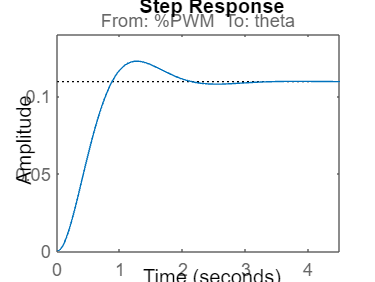

clear; clc; close all; 
addpath("data\")
ang_Lin = 80;
[Gss] = getNewTF(ang_Lin);
step(Gss); %% Lazo abierto de planta

Definición de las prestaciones: 

- Seguimiento de Referencia Perfecto (ep = 0) 

- Accion de Control entre (0 < u < 100) [ % PWM ]

- Menor tiempo posible (Mayor ancho de banda) 

- Rechazo a perturbaciones 

Definición de señales 

- ***El controlador recibe error en radianes y lo convierte a Porcentaje de PWM % ***

## Definición Reference Model

Se define el modelo de referencia


$$\textrm{ReferenceModel}\;=\frac{a_{\textrm{ss}}^* }{s^2 +c_{\textrm{ss}}^* \cdot s+b_{\textrm{ss}}^* }=A_m \cdot x+B_m \cdot u$$


 Donde las matrices $A_m$ y $B_m$ se relacionan con la ecuación de la siguiente manera.


$$A_m =\left\lbrack \begin{array}{cc}
0 & 1\\
b_{\textrm{ss}}^*  & c_{\textrm{ss}}^* 
\end{array}\right\rbrack \;\;\;\;\;\;\;B_m =\left\lbrack \begin{array}{c}
0\\
a_{\textrm{ss}}^* 
\end{array}\right\rbrack$$


% Definición de parámetros
bss = -8.912;
css = -5.5;
ass = 0.9745;
% Grafica de filtros 
A_RM = [0 1; bss, css];
B_RM = [0 0.2*ass]';
C_RM = [1 0;0 1];
D_RM = [0];

GRM = ss(A_RM, B_RM, C_RM, D_RM);
GRM.StateName= {'theta','omega'};
GRM.OutputName= {'theta','omega'};
GRM.InputName = {'%PWM'};

## **Comparación de Modelos**

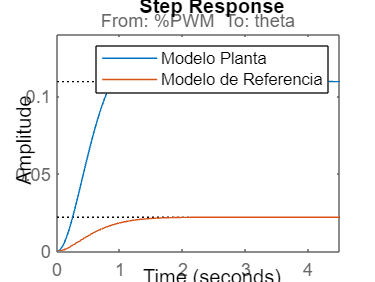

figure()
step(Gss);
hold on
step(GRM(1,1));
hold off
legend('Modelo Planta','Modelo de Referencia');


stepinfo(Gss)

ans = struct with fields:
         RiseTime: 0.5891
    TransientTime: 1.9601
     SettlingTime: 1.9601
      SettlingMin: 0.1004
      SettlingMax: 0.1225
        Overshoot: 12.0677
       Undershoot: 0
             Peak: 0.1225
         PeakTime: 1.2708


stepinfo(GRM(1,1))

ans = struct with fields:
         RiseTime: 0.9982
    TransientTime: 1.6527
     SettlingTime: 1.6527
      SettlingMin: 0.0198
      SettlingMax: 0.0219
        Overshoot: 0.0589
       Undershoot: 0
             Peak: 0.0219
         PeakTime: 2.6961


## MRAC Ideal

kri = Gss.B\GRM.B

kri = 0.2000

Kxi = Gss.B\(GRM.A-Gss.A)

Kxi =     0.0004   -2.2226



GMRAC=ss(Gss.A+Gss.B*Kxi, Gss.B*kri, [1,0],[0]);
GMRAC.StateName= {'theta','omega'};
GMRAC.OutputName= {'theta'};
GMRAC.InputName = {'%PWM'}

GMRAC =
 
  A = 
           theta   omega
   theta       0       1
   omega  -8.912    -5.5
 
  B = 
            %PWM
   theta       0
   omega  0.1949
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          %PWM
   theta     0
 
Continuous-time state-space model.



## Validación respuestas al escalón

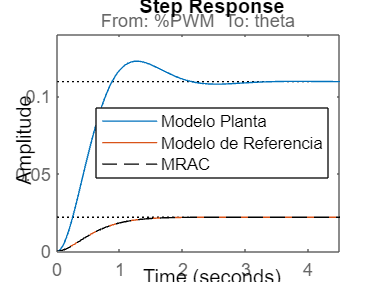

figure()
step(Gss);
hold on
step(GRM(1,1));
step(GMRAC(1,1),'k--');
hold off
legend('Modelo Planta','Modelo de Referencia','MRAC','Location','east');

## Leyes de adaptación


$${\overset{\bullet }{K_x } }^T =\Gamma_x \cdot x\cdot e^T \cdot \overset{-}{P} \cdot \textrm{sgn}\;b$$



$$\overset{\bullet }{k_r } =\gamma_r \cdot r\cdot e^T \cdot \overset{-}{P} \cdot \textrm{sgn}\;b$$


## Ley de Control


$$u\;=K_x \left(t\right)\cdot x+k_r \left(t\right)\cdot r$$


Q = eye(2);
R = 10;
[K, Pmatrix, P] = lqr(GRM,Q,R);
Pbarra = Pmatrix*[0 1]';
Gamma_x = [700 0; 0 1];%60*eye(2);
gamma_r = 30;

syms P11 P12 P21 P22
P = [P11 P12; P21 P22];
Sol = solve(GRM.A'*P+P*GRM.A+Q==0)

Sol = struct with fields:
    P11: 7411609/6127000
    P12: 125/2228
    P21: 125/2228
    P22: 1239/12254


Sol = [Sol.P11 Sol.P12; Sol.P21 Sol.P22]

$$Sol = \left(\begin{array}{cc} \frac{7411609}{6127000} & \frac{125}{2228}\\ \frac{125}{2228} & \frac{1239}{12254} \end{array}\right)$$

Pmatrix2 = double(Sol)

Pmatrix2 =     1.2097    0.0561
    0.0561    0.1011


Pmatrix

Pmatrix =     1.2096    0.0561
    0.0561    0.1011


## Simulación

load("data/TF.mat")
load("data/observer.mat");